% Clear workspace and command window
clear; clc; close all;

%% 1. Initialize and Load the Network
inp_file = 'Net1.inp'; 
d = epanet(inp_file);

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.



%% 2. Configure Water Quality parameters
d.setQualityType('CHEM', 'mg/L'); 

% Apply decay rates using correct official toolkit array properties
num_links = d.getLinkCount;
d.setLinkBulkReactionCoeff(ones(1, num_links) * -0.6); 
d.setLinkWallReactionCoeff(ones(1, num_links) * -1.2); 

% Define the injection node index
target_node_index = 1; 

%% 3. Run Extended Period Water Quality Simulation (With Cyclical Schedule)
duration = d.getTimeSimulationDuration;
hyd_step = d.getTimeHydraulicStep;

time_steps = [];
node_quality_history = [];
current_time = 0;
step_index = 1;

while current_time <= duration
    % --- CYCLICAL INJECTION LOGIC ---
    current_hour = current_time / 3600;
    
    % Modulo arithmetic creates an 8-hour repeating block cycle
    % (First 4 hours = ON, next 4 hours = OFF)
    if mod(current_hour, 8) < 4
        current_injection = 1.5; % ON phase (mg/L)
    else
        current_injection = 0.0; % OFF phase (mg/L)
    end
    
    % Update the source node quality dynamically for this step
    d.setNodeInitialQuality(target_node_index, current_injection);
    
    % Solve hydraulics and quality transport matrices
    d.solveCompleteHydraulics;
    
    % Save tracking records
    time_steps(step_index) = current_hour; 
    node_quality_history(:, step_index) = d.getNodeActualQuality; 
    
    current_time = current_time + hyd_step;
    step_index = step_index + 1;
end
disp('Water quality cyclical simulation loop complete.');

Water quality cyclical simulation loop complete.


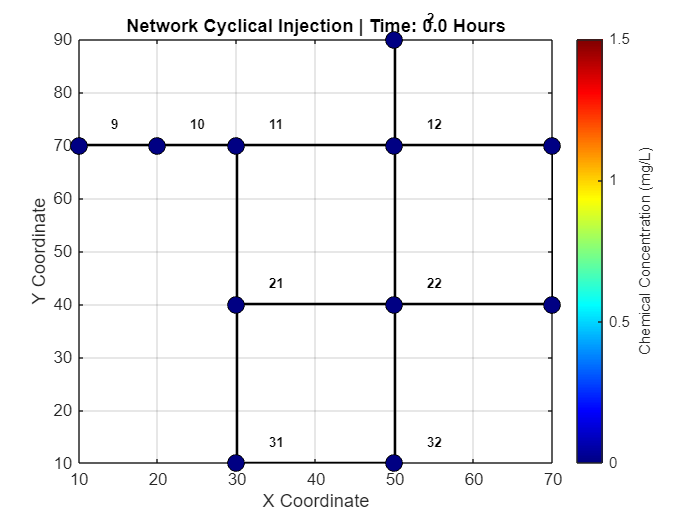

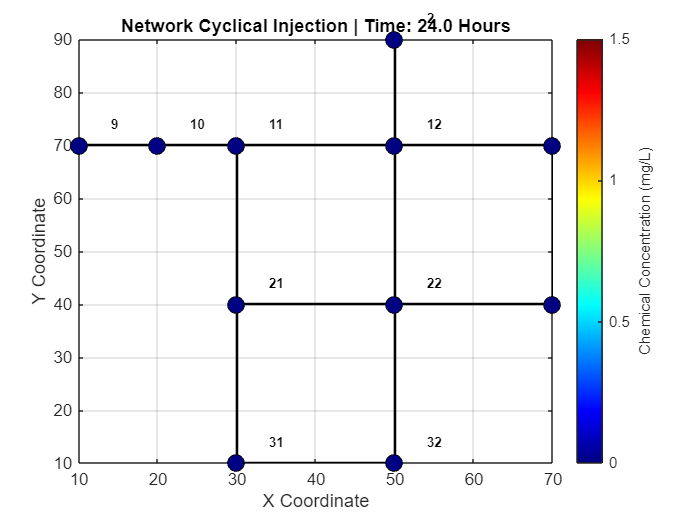


%% 4. Animate Spatial Distribution Over Time
% Extract coordinates from the cell structure accurately
coords_cell = d.getNodeCoordinates; 
x_coords = coords_cell{1}; 
y_coords = coords_cell{2}; 

link_nodes = d.getLinkNodesIndex; 
node_ids = d.getNodeNameID;

% Initialize the animation figure window
fig = figure('Name', 'Cyclical Water Quality Animation', 'NumberTitle', 'off');

% Determine fixed colorbar limit based on the maximum tracked value
max_val = max(node_quality_history(:));
if max_val <= 0, max_val = 1.5; end 

% Loop through each simulated time step to update the plot
for t = 1:length(time_steps)
    clf(fig); 
    hold on; grid on; box on;
    
    % Draw network pipelines
    for i = 1:num_links
        from_node = link_nodes(i, 1);
        to_node = link_nodes(i, 2);
        plot([x_coords(from_node), x_coords(to_node)], ...
             [y_coords(from_node), y_coords(to_node)], ...
             'k-', 'LineWidth', 1.5);
    end
    
    % Draw Nodes color-coded by concentration at current time step 't'
    spatial_quality = node_quality_history(:, t);
    scatter(x_coords, y_coords, 100, spatial_quality, 'filled', 'MarkerEdgeColor', 'k');
    
    % Formatting visual elements with a native MATLAB colormap
    colormap('jet'); 
    clim([0, max_val]); 
    cb = colorbar;
    ylabel(cb, 'Chemical Concentration (mg/L)');
    
    title(['Network Cyclical Injection | Time: ', num2str(time_steps(t), '%.1f'), ' Hours']);
    xlabel('X Coordinate'); ylabel('Y Coordinate');
    
    % Overlay text tags for individual node names
    for i = 1:d.getNodeCount
        text(x_coords(i) + 4, y_coords(i) + 4, node_ids{i}, 'FontSize', 8, 'FontWeight', 'bold');
    end
    
    hold off;
    drawnow;   
    pause(0.2); % Faster playback to clearly observe the chemical waves traveling
end


%% 5. Unload Toolkit
d.unload;

EPANET Class is unloaded


disp('Animation loop complete.');

Animation loop complete.
